# 線形回帰（単回帰分析）を1から実装して理解を深めてみよう

この記事は、MATLABアドベントカレンダー（その2）の4日目の記事として書かれています。

[https://qiita.com/advent-calendar/2022/matlab](https://qiita.com/advent-calendar/2022/matlab)

## 1 はじめに

以下の図のように、エクセルなどで、直線で回帰する（フィッティング）した経験がある方も多いかもしれません。

以下の図では、y = 0.33x + 50.2 という式が得られています。

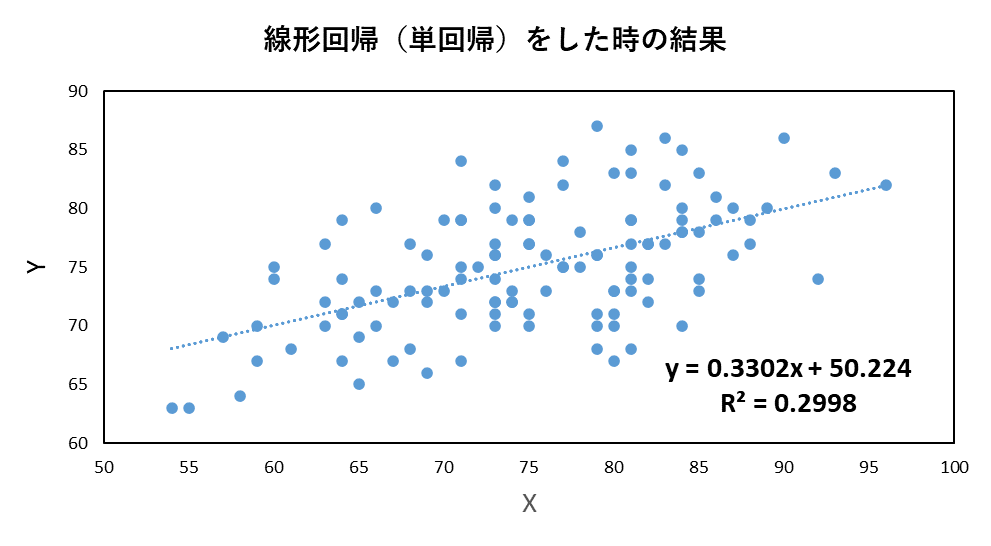

さらにaについて解くことで、


$$a\;=\;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }$$


...(17)

となりました。この結果を(14)に代入して、


$$b=-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$


...(18)

となりました。これにより、傾きと切片の値を求めることができました。


$$T_{\mathrm{xy}} =\sum_{i=1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)$$


**共分散の意味と簡単な求め方**

[https://manabitimes.jp/math/853](https://manabitimes.jp/math/853)


$$T_{\mathrm{xy}} =\sum_{i=1}^N x_i y_i -\frac{1}{n}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i \;$$



$$a\;=\;\frac{\sum_{i\;=\;1}^N x_i y_i \;-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\sum_{i\;=\;1}^N y_i }{\sum_{i\;=\;1}^N {x_i }^2 -\frac{1}{N}{\left(\sum_{i\;=\;1}^N x_i \;\right)}^2 }$$



$$=\frac{\sum_{i=1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)}{\sum_{i=1}^N {\left(x_i -\bar{x} \right)}^2 }$$



$$=\frac{T_{\mathrm{xy}} }{T_{\mathrm{xx}} }$$



$$=\frac{T_{\mathrm{xy}} \times \frac{1}{n}}{T_{\mathrm{xx}} \times \frac{1}{n}}$$



$$=\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }$$



$$b=-\frac{1}{N}a\sum_{i\;=\;1}^N x_i \;+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$


...(14)


$$b=-\frac{1}{N}\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }\sum_{i\;=\;1}^N x_i \;+\frac{1}{N}\sum_{i\;=\;1}^N y_i \;$$



$$=-\frac{1}{N}\sum_{i\;=\;1}^N x_i \;\times \;\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }+\frac{1}{N}\sum_{i\;=\;1}^N y_i$$



$$=\bar{y} -\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }\;\bar{x} \;\;$$
 

平方和の分解


$$S_{\mathrm{yy}} \;\mathrm{＝}\;\sum_{i\;=\;1}^N {\left(y_i -\bar{y} \right)}^2$$



$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)+\left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$



$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 +\;\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2 +2\sum_{i\;=\;1}^N \left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$\sum_{i\;=\;1}^N \left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$e_i =y_i -\left({ax}_i +b\right)\;$$



$$\sum_{i\;=\;1}^N e_i =0$$



$$\sum_{i\;=\;1}^N e_i x_i =0$$



$$\sum_{i\;=\;1}^N e_i \left\lbrace \left({ax}_i +b\right)-\bar{\left.y\right\rbrace } \right.$$



$$=\left(b-\bar{y} \right)\sum_{i\;=\;1}^N e_i +a\;\sum_{i\;=\;1}^N e_i x_{i\;} =0$$

$$\;$$



$$=\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 +\;\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$



$$\sum_{i\;=\;1}^N {\left\lbrace y_i -\left({ax}_i +b\right)\right\rbrace }^2 \;$$


平均点を通るので


$$＝\;\sum_{i\;=\;1}^N {\left\lbrace y_i -\bar{y} -a\left(x-\bar{x} \right)\right\rbrace }^2 \;$$



$$＝\;\sum_{i\;=\;1}^N {\left(y_i -\bar{y} \right)}^2 -2a\sum_{i\;=\;1}^N \left(x_i -\bar{x} \right)\left(y_i -\bar{y} \right)+a^2 \sum_{i\;=\;1}^N {\left(x_i -\bar{x} \right)}^2$$


*a*を１つだけ展開


$${=\;S}_{\mathrm{yy}} -2aS_{\mathrm{xy}} +a\frac{S_{\mathrm{xy}} }{S_{\mathrm{xx}} }S_{\mathrm{xx}}$$



$${=\;S}_{\mathrm{yy}} -aS_{\mathrm{xy}}$$
　　　　    　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　　
$${\;S}_{\mathrm{yy}} =aS_{\mathrm{xy}} +{\;S}_e$$



$${\;S}_{\mathrm{yy}} ={\;S}_e +S_R$$
　　


$$S_R =\sum_{i\;=\;1}^N {\left\lbrace \left({ax}_i +b\right)-\bar{y} \right\rbrace }^2$$
　　　　　　　　　　


$$=aS_{\mathrm{xy}}$$


= $\frac{{S_{\mathrm{xy}} }^2 }{S_{\mathrm{xx}} }$


$$R^2 =\frac{S_R }{{\;S}_{\mathrm{yy}} }=\frac{S_{\mathrm{yy}} -S_e }{{\;S}_{\mathrm{yy}} }=1-\frac{S_e }{{\;S}_{\mathrm{yy}} }$$



$$R^2 =\frac{S_R }{{\;S}_{\mathrm{yy}} }=\frac{\frac{{S_{\mathrm{xy}} }^2 }{S_{\mathrm{xx}} }}{{\;S}_{\mathrm{yy}} }={\left(\frac{S_{\mathrm{xy}} }{\sqrt{S_{\mathrm{xx}} S_{\mathrm{yy}} }}\right)}^2 \;={r_{\mathrm{xy}} }^2 \;$$


load examgrades

yとXの値を設定します。

y = grades(:,5);
X = [ones(size(grades(:,1))) grades(:,1)];

regress関数で単回帰分析を行います。

[mdl,~,r,rint,stats] = regress(y,X);
disp(strcat('R2_MATLAB= ',string(stats(1))))

x = grades(:,1);
bunshi_a = sum(x.*y)-1/numel(x)*sum(x)*sum(y);

R^2=0.2998


bumbo_a = sum(x.^2)-1/numel(x)*(sum(x)^2);
a = bunshi_a/bumbo_a;
b = -1/numel(x)*sum(x)*a+1/numel(x)*sum(y);
SR = sum((a*x+b-mean(y)).^2);
Syy = sum((y-mean(y)).^2);
R2 = SR/Syy

R2 = 0.2998